# Quarter Car Model for Suspension

The provided MATLAB code is used to simulate a quarter car model for suspension using ordinary differential equations (ODEs). The model represents a car suspension system and involves several parameters and variables.

$k$ is car spring constant (N/m) and $c$ is car damping coefficient (N/(m/s) ).

$M_c$ is car body mass (kg ) and $M_t$ is tyre mass (kg).

$S_c$ is car body displacement and $S_t$ is tyre displacement.

$V_c$ is velocity of car body and $V_t$ is tyre velocity.

$R$ is road profile.

These equations are used to solve the ODEs and simulate the behavior of the quarter car suspension system:

#### 
$$\begin{array}{l}
\frac{\mathrm{d}}{\mathrm{d}t}S_c =V_c \;,\\
\frac{\mathrm{d}}{\mathrm{d}t}V_c =\frac{\left(-k*\left(\left(S_c -S_t -R\right)\right)-c*\left(V_c -V_t \right)\right)}{M_c }\\
\begin{array}{l}
\frac{\mathrm{d}}{\mathrm{d}t}S_t =V_t \;,\\
\frac{\mathrm{d}}{\mathrm{d}t}V_t =\frac{\left(k*\left(\left(S_c -S_t -R\right)\right)+c*\left(V_c -V_t \right)\right)}{M_t }
\end{array}
\end{array}$$


% Road profiles
road1 = @(t) 0.4 *((t >= 0.2) - (t >= 0.8)); % single square 
road2 = @(t) 0.4*square(2*pi*t); % periodic square wave

% Parameters
p = [600; 50; 80000; 1000]; % [m1; m2; k1; c1]

% Initial conditions
x0 = [0; 0; 0; 0]; % [x1; v1; x2; v2]

% Time span
tspan = [0 2]; % Specify the start and end times of the simulation

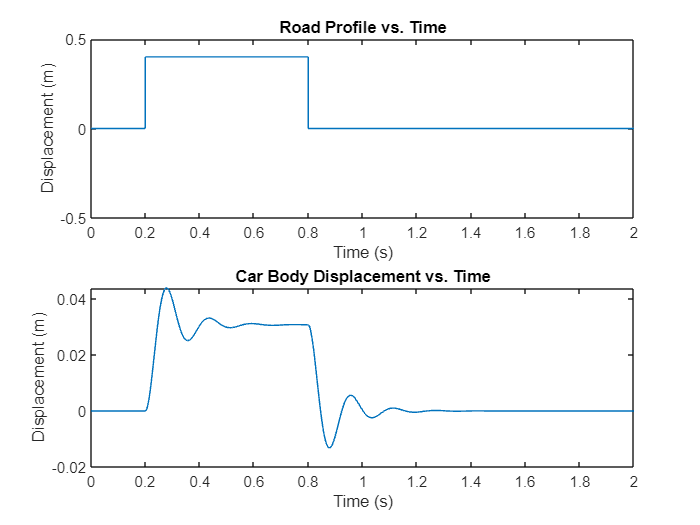

% Solve the ODE and plot result
[t, x] = ode45(@(t, x) suspensionODE(t, x, p, road1), tspan, x0); % Pass road as an additional parameter
plotResults(t,x,road1);

The plotted results confirm that the car suspension system is functioning as designed. Notable changes in the road surface occur at t = 0.2 seconds, transitioning the car's position from 0 to 0.4 meters. By t = 0.6 seconds, approximately 0.4 seconds after the surface change, the impact of the road alteration has already been mitigated. At t = 0.8 seconds, another surface change takes place, causing the car's position to shift from 0.4 meters to 0 meters. Similar to the previous change, it takes approximately 0.4 seconds for the suspension system to effectively reduce the impact of the surface difference.

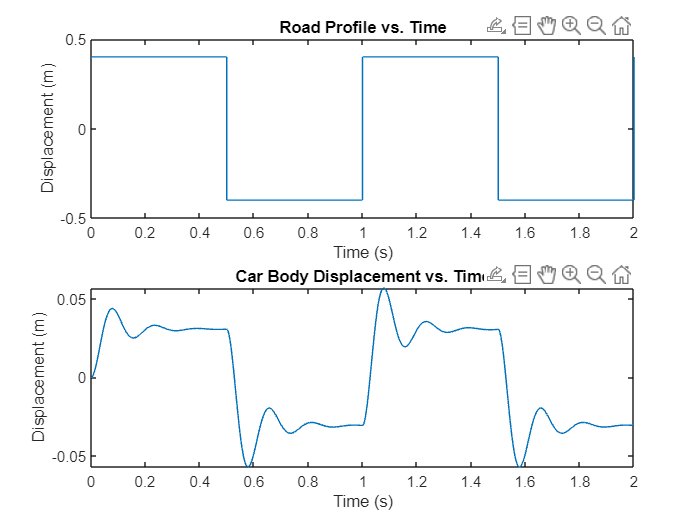

% use road2 profile
% Solve the ODE and plot result
[t, x] = ode45(@(t, x) suspensionODE(t, x, p, road2), tspan, x0); % Pass road as an additional parameter
plotResults(t,x,road2);

The plot demonstrates that the car's suspension system is capable of handling repeated surface changes effectively. Specifically, it can handle the transition from a 0.5-meter high ground to a 0.5-meter depth in the road surface.

During these surface changes, the car's suspension system successfully maintains stability and prepares the car to handle the next road impact. This indicates that the suspension system is efficiently absorbing and mitigating the effects of the surface variations, allowing the car to remain in a controlled and stable state throughout the transitions.

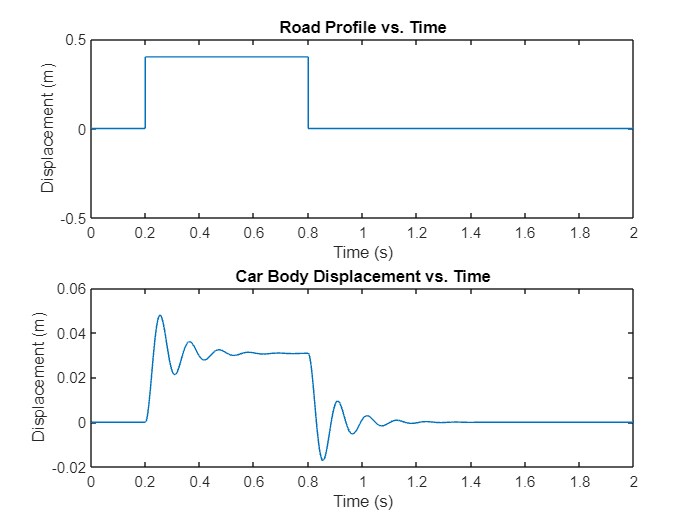

%change stiffness of the spring to 2*k

% 2*k (car spring constant)
p(3) = 2*p(3);

% Solve the ODE and plot result
[t, x] = ode45(@(t, x) suspensionODE(t, x, p, road1), tspan, x0); % Pass road as an additional parameter
plotResults(t,x,road1);

By doubling the spring stiffness (k = 2 * k), the plot still depicts a similar process to the previous scenario. However, there are a few notable differences.

The plot shows three peaks before the car reaches stability. These peaks are a result of the damper having a harder time damping the oscillations caused by the stiffer spring. The increased stiffness leads to greater energy transfer, resulting in more pronounced oscillations.

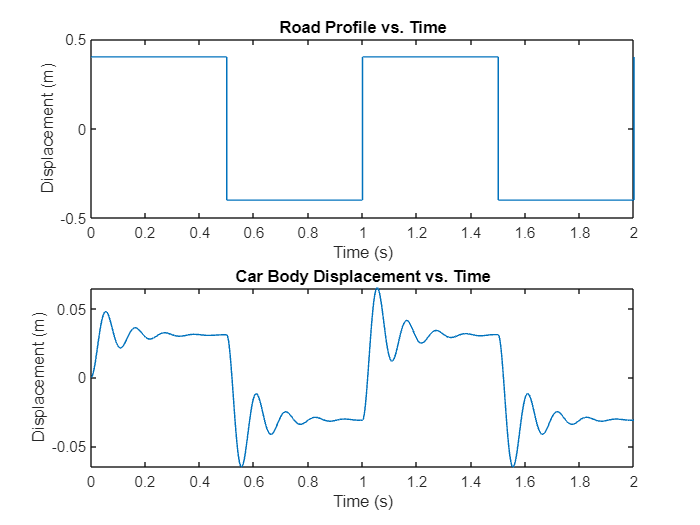

% use road2 profile
% Solve the ODE and plot result
[t, x] = ode45(@(t, x) suspensionODE(t, x, p, road2), tspan, x0); % Pass road as an additional parameter
plotResults(t,x,road2);

Despite the challenges posed by the increased oscillations, the suspension system effectively prepares the car for the next impact, ensuring it remains stable and capable of handling future obstacles.

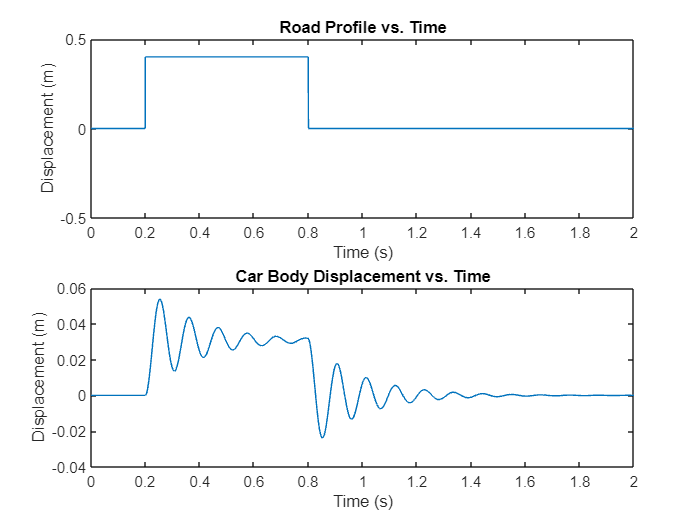

%change damping coefficient of suspension to 0.5*c

% 0.5*c (damping coefficient)
p(4) = 0.5*p(4);

% Solve the ODE and plot result
[t, x] = ode45(@(t, x) suspensionODE(t, x, p, road1), tspan, x0); % Pass road as an additional parameter
plotResults(t,x,road1);

When the damping coefficient of the suspension is decreased while the stiffness is increased, it leads to a longer time for the car suspension system to reach stability. In the plot, it is evident that the suspension system struggles to fully dampen the road surface disturbances.

The reduced damping coefficient means that there is less resistance to the oscillations induced by the increased stiffness. As a result, the car suspension system takes more time to dissipate the energy and bring the car to a stable state.

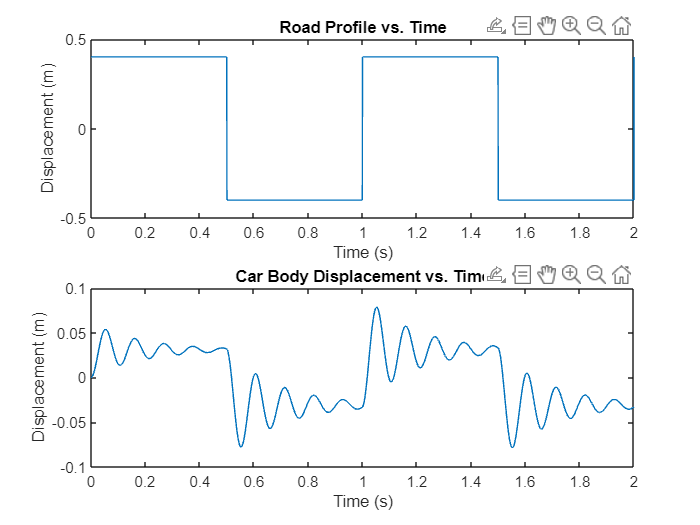

% use road2 profile
% Solve the ODE and plot result
[t, x] = ode45(@(t, x) suspensionODE(t, x, p, road2), tspan, x0); % Pass road as an additional parameter
plotResults(t,x,road2);

The fact that the suspension system fails to fully dampen the road surface suggests that incorrect suspension components, such as insufficient damping with high stiffness, can lead to a dangerous situation. The car may experience prolonged oscillations, compromising stability and potentially affecting the handling and safety of the vehicle.

It emphasizes the importance of selecting appropriate suspension components that are well-matched in terms of stiffness and damping to ensure effective control, stability, and safe operation of the vehicle.

function dxdt = suspensionODE(t, x, p, road)

    % Parameters
    m1 = p(1); % kg (car body mass)
    m2 = p(2); % kg (tire mass)
    k1 = p(3); % N/m (car spring constant)
    c1 = p(4); % N/(m/s) (car damping coefficient)

    % State variables
    x1 = x(1); % Car body displacement
    v1 = x(2); % Car body velocity
    x2 = x(3); % Tire displacement
    v2 = x(4); % Tire velocity

    % Equations of motion
    dxdt = zeros(4, 1);
    dxdt(1) = v1;
    dxdt(2) = (-k1 * (x1 - x2 - road(t)) - c1 * (v1 - v2)) / m1;
    dxdt(3) = v2;
    dxdt(4) = (k1 * (x1 - x2 - road(t)) + c1 * (v1 - v2)) / m2;
end

function plotResults(t, x, road)
    % Extract the variables from the solution
    x1 = x(:, 1); % Car body displacement
    v1 = x(:, 2); % Car body velocity
    x2 = x(:, 3); % Tire displacement
    v2 = x(:, 4); % Tire velocity

    % Plot the results
    figure;
    subplot(2, 1, 1);
    plot(t, road(t));
    xlabel('Time (s)');
    ylabel('Displacement (m)');
    title('Road Profile vs. Time');
    ylim([-0.5 0.5])
    subplot(2, 1, 2);
    plot(t, x1);
    xlabel('Time (s)');
    ylabel('Displacement (m)');
    title('Car Body Displacement vs. Time');

end
